clear
close all

Env = xlsread('S3_CTD.xlsx'); 


IDXwinter = find (Env (:,2)==2);
winter=Env(IDXwinter,:);

IDXspring = find (Env (:,2)==4);
spring=Env(IDXspring,:);

IDXsummer = find (Env (:,2)==8);
summer=Env(IDXsummer,:);

dateW = winter (:,1:3);
dateS = spring (:,1:3);
dateSM = summer (:,1:3);

dateWN = datenum (dateW);
dateSN = datenum (dateS);
dateSMN = datenum (dateSM);



stW = winter (:,4);
stS = spring (:,4);
stSM = summer (:,4);

depthW = winter (:,5);
depthS = spring (:,5);
depthSM = summer (:,5);

TempNW = winter (:,6);
SalNW = winter (:,7);
FluoNW = winter (:,8);
TurbW = winter (:,9);
ParNW = winter (:,10);

TempNS = spring (:,6);
SalNS = spring (:,7);
FluoNS = spring (:,8);
TurbS = spring (:,9);
ParNS = spring (:,10);

TempNSM = summer (:,6);
SalNSM = summer (:,7);
FluoNSM = summer (:,8);
TurbSM = summer (:,9);
ParNSM = summer (:,10);


## Interpolacion


% %interpolacion de la variable x
dateINTW=[linspace(min(dateWN),max(dateWN),9)];%aquí empezarías tú, tendrías que poner tu variable x, que es distancia, no sé si lo tienes en longitud, imagino que si
dateINTS=[linspace(min(dateSN),max(dateSN),9)]

dateINTS = 	1.0e+05 *

    7.3642    7.3642    7.3642    7.3642    7.3642    7.3643    7.3643    7.3643    7.3643


dateINTSM=[linspace(min(dateSMN),max(dateSMN),9)]

dateINTSM = 	1.0e+05 *

    7.3654    7.3654    7.3654    7.3655    7.3655    7.3655    7.3655    7.3655    7.3655



presINT=(1:5:75)'; %creas tu variable profundidad según la prof maxima de tus estaciones. Por ejemplo si tu profundidad máxima es 100, pues creas la variable pres cada metro por ejemplo d ela siguiente forma: pres=(0:1:100)';

[x1d,y1d]=meshgrid(dateINTW,presINT); %creas una malla usando tu variable x (distancia) y tu variable y (profundidad)
[x2d,y2d]=meshgrid(dateINTS,presINT);
[x3d,y3d]=meshgrid(dateINTSM,presINT);
% Interpolacion dee las variables ambientales
%interpolas tu variable, en este caso el nitrato, sobre la malla que acabas de crear (yo le llame x1d e y1d al a malla)



## Interpolacion Winter


Temp_INT_W = gridfit(dateWN(isfinite(TempNW)),depthW(isfinite(TempNW)),TempNW(isfinite(TempNW)),x1d(1,:),y1d(:,1)); 

Sal_INT_W = gridfit(dateWN(isfinite(SalNW)),depthW(isfinite(SalNW)),SalNW(isfinite(SalNW)),x1d(1,:),y1d(:,1)); 

Fluo_INT_W = gridfit(dateWN(isfinite(FluoNW)),depthW(isfinite(FluoNW)),FluoNW(isfinite(FluoNW)),x1d(1,:),y1d(:,1)); 

Turb_INT_W = gridfit(dateWN(isfinite(TurbW)),depthW(isfinite(TurbW)),TurbW(isfinite(TurbW)),x1d(1,:),y1d(:,1)); 

Par_INT_W = gridfit(dateWN(isfinite(ParNW)),depthW(isfinite(ParNW)),ParNW(isfinite(ParNW)),x1d(1,:),y1d(:,1)); 



Temp_INT_S = gridfit(dateSN(isfinite(TempNS)),depthS(isfinite(TempNS)),TempNS(isfinite(TempNS)),x2d(1,:),y2d(:,1)); 

Sal_INT_S = gridfit(dateSN(isfinite(SalNS)),depthS(isfinite(SalNS)),SalNS(isfinite(SalNS)),x2d(1,:),y2d(:,1)); 

Fluo_INT_S = gridfit(dateSN(isfinite(FluoNS)),depthS(isfinite(FluoNS)),FluoNS(isfinite(FluoNS)),x2d(1,:),y2d(:,1)); 

Turb_INT_S = gridfit(dateSN(isfinite(TurbS)),depthS(isfinite(TurbS)),TurbS(isfinite(TurbS)),x2d(1,:),y2d(:,1)); 

Par_INT_S = gridfit(dateSN(isfinite(ParNS)),depthS(isfinite(ParNS)),ParNS(isfinite(ParNS)),x2d(1,:),y2d(:,1)); 



Temp_INT_SM = gridfit(dateSMN(isfinite(TempNSM)),depthSM(isfinite(TempNSM)),TempNSM(isfinite(TempNSM)),x3d(1,:),y3d(:,1)); 

Sal_INT_SM = gridfit(dateSMN(isfinite(SalNSM)),depthSM(isfinite(SalNSM)),SalNSM(isfinite(SalNSM)),x3d(1,:),y3d(:,1)); 

Fluo_INT_SM = gridfit(dateSMN(isfinite(FluoNSM)),depthSM(isfinite(FluoNSM)),FluoNSM(isfinite(FluoNSM)),x3d(1,:),y3d(:,1)); 

Turb_INT_SM = gridfit(dateSMN(isfinite(TurbSM)),depthSM(isfinite(TurbSM)),TurbSM(isfinite(TurbSM)),x3d(1,:),y3d(:,1)); 

Par_INT_SM = gridfit(dateSMN(isfinite(ParNSM)),depthSM(isfinite(ParNSM)),ParNSM(isfinite(ParNSM)),x3d(1,:),y3d(:,1)); 

## Figurras invierno

## Temp

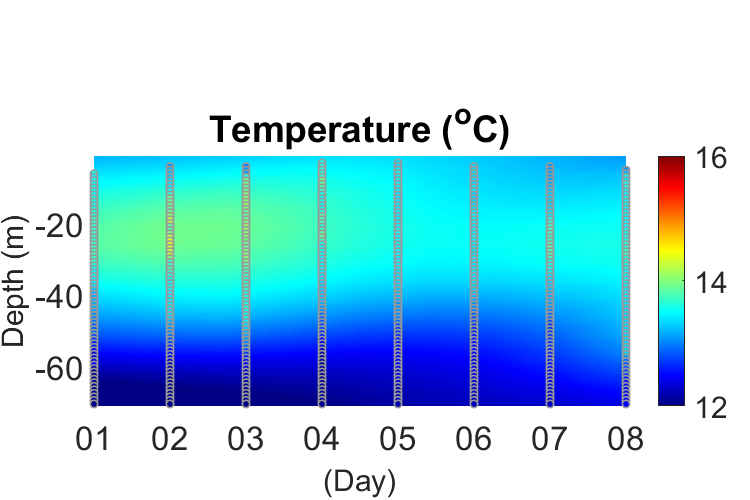

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,Temp_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Temperature (^oC)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet');
cb=colorbar;
caxis([12 16]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(TempNW)),-depthW(isfinite(TempNW)),20,TempNW(isfinite(TempNW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S3_Temp.png','Resolution',300)

## Sal

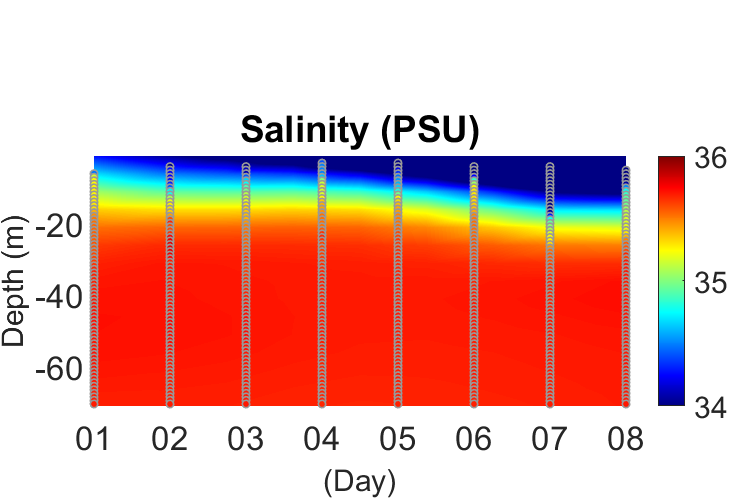

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,Sal_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Salinity (PSU)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); 
cb=colorbar;
caxis([34 36]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(SalNW)),-depthW(isfinite(SalNW)),20,SalNW(isfinite(SalNW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S3_Sal.png','Resolution',300)

## Fluo

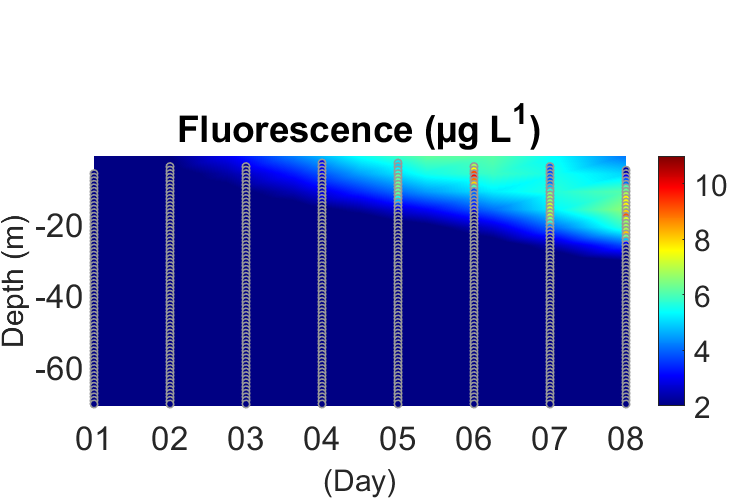

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,Fluo_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Fluorescence (µg L^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([2 11]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(FluoNW)),-depthW(isfinite(FluoNW)),20,FluoNW(isfinite(FluoNW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S3_Fluo.png','Resolution',300)

## Turb

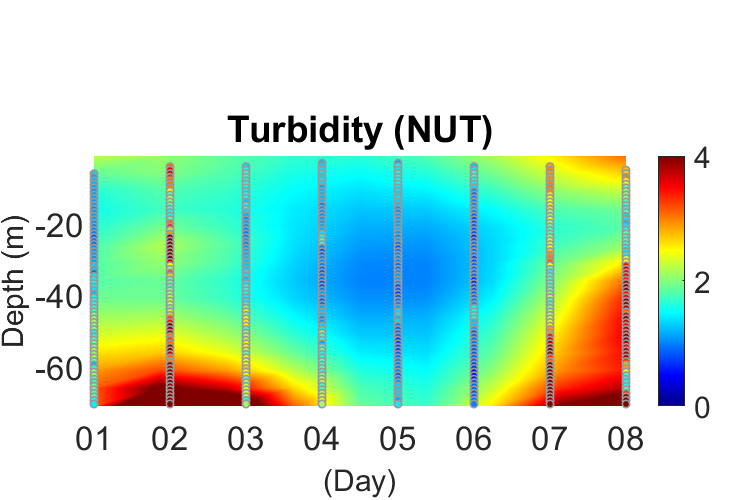

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,Turb_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Turbidity (NUT)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 4]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(TurbW)),-depthW(isfinite(TurbW)),20,TurbW(isfinite(TurbW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S3_Turb.png','Resolution',300)

## Par

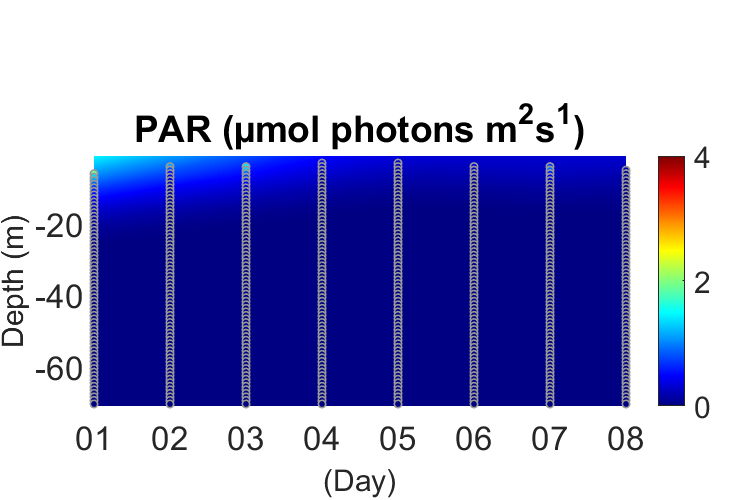

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTW,-presINT,Par_INT_W); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'PAR (µmol photons m^2s^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 4]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateWN(isfinite(ParNW)),-depthW(isfinite(ParNW)),20,ParNW(isfinite(ParNW)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Winter_S3_Par.png','Resolution',300)

## Spring

## Temp

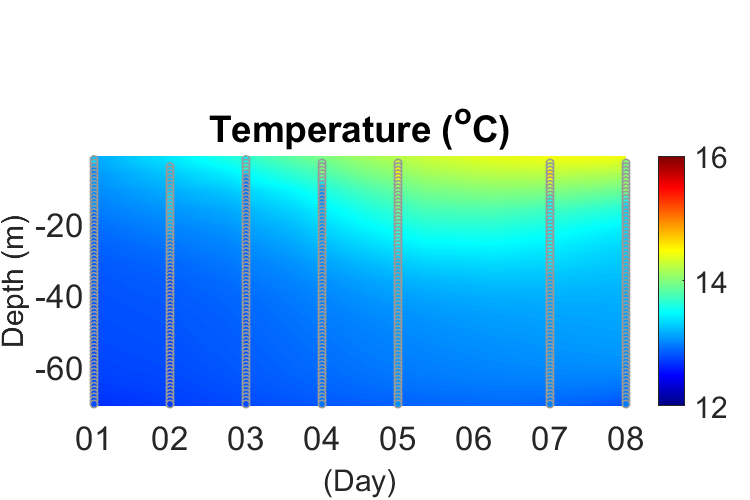

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,Temp_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Temperature (^oC)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet');
cb=colorbar;
caxis([12 16]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(TempNS)),-depthS(isfinite(TempNS)),20,TempNS(isfinite(TempNS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S3_Temp.png','Resolution',300)

## Sal

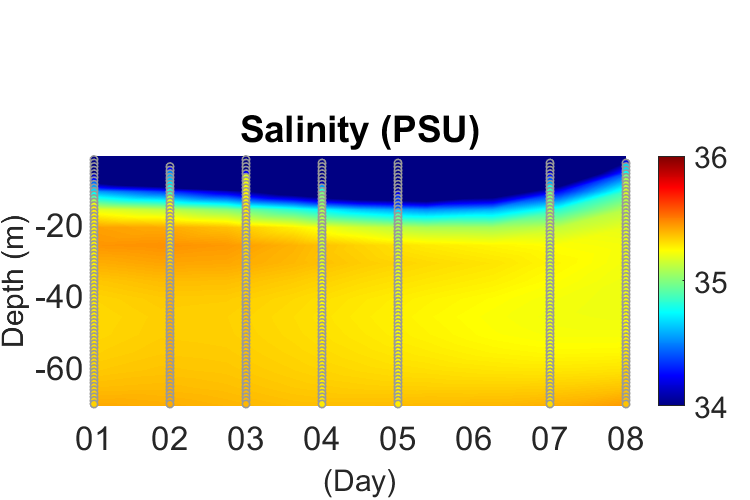

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,Sal_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Salinity (PSU)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); 
cb=colorbar;
caxis([34 36]);   % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(SalNS)),-depthS(isfinite(SalNS)),20,SalNS(isfinite(SalNS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S3_Sal.png','Resolution',300)

## Fluo

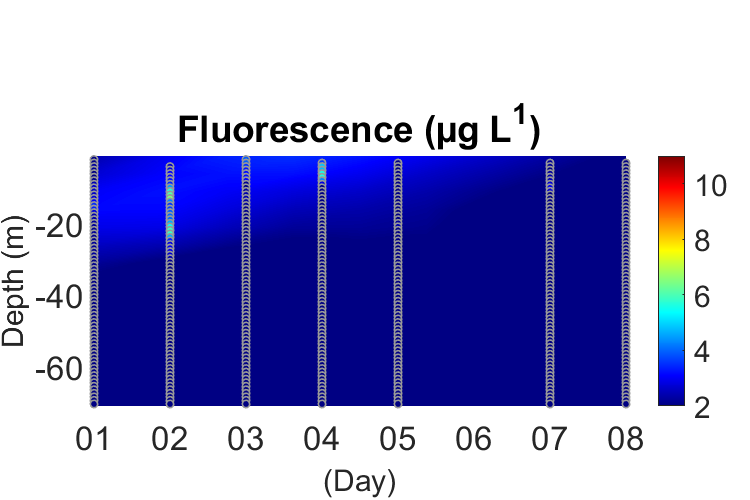

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,Fluo_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Fluorescence (µg L^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([2 11]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(FluoNS)),-depthS(isfinite(FluoNS)),20,FluoNS(isfinite(FluoNS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S3_Fluo.png','Resolution',300)

## Turb

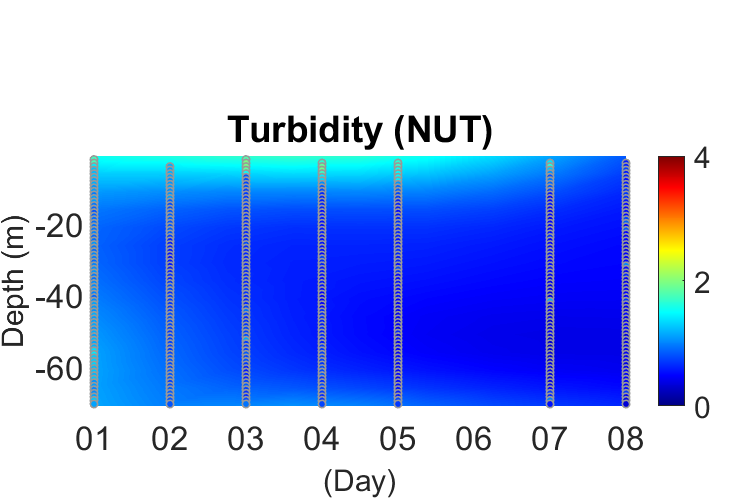

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,Turb_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Turbidity (NUT)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 4]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(TurbS)),-depthS(isfinite(TurbS)),20,TurbS(isfinite(TurbS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S3_Turb.png','Resolution',300)

## Par

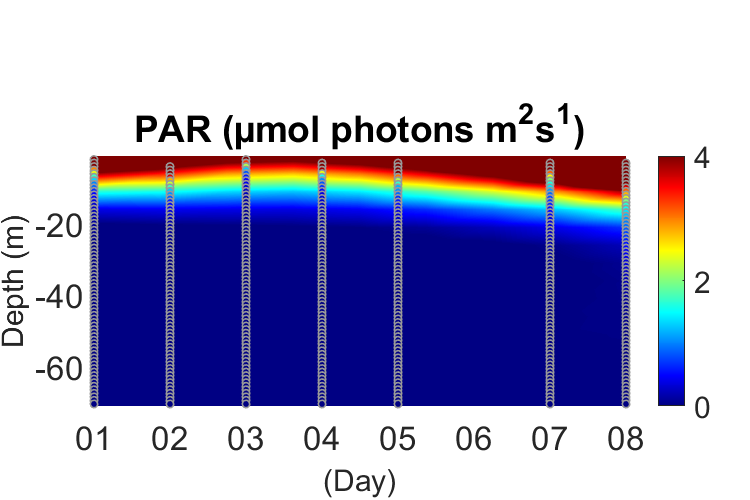

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTS,-presINT,Par_INT_S); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'PAR (µmol photons m^2s^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 4]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSN(isfinite(ParNS)),-depthS(isfinite(ParNS)),20,ParNS(isfinite(ParNS)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Spring_S3_Par.png','Resolution',300)

## Verano

## Temp

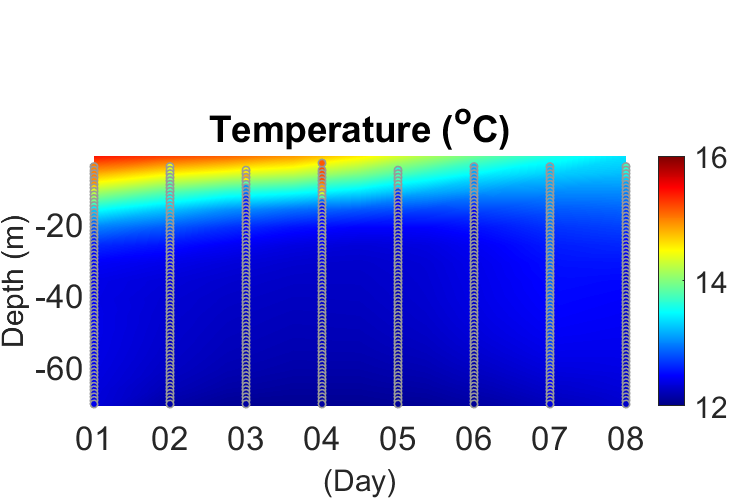

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,Temp_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Temperature (^oC)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet');
cb=colorbar;
caxis([12 16]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(TempNSM)),-depthSM(isfinite(TempNSM)),20,TempNSM(isfinite(TempNSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S3_Temp.png','Resolution',300)

## Sal

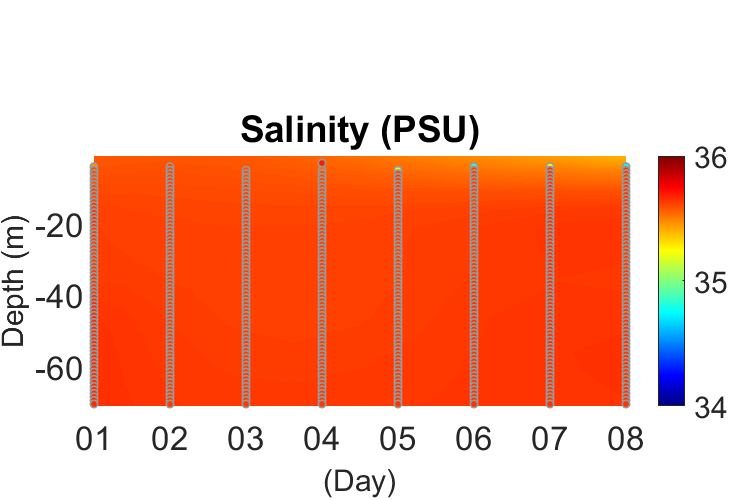

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,Sal_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Salinity (PSU)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); 
cb=colorbar;
caxis([34 36]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(SalNSM)),-depthSM(isfinite(SalNSM)),20,SalNSM(isfinite(SalNSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S3_Sal.png','Resolution',300)

## Fluo

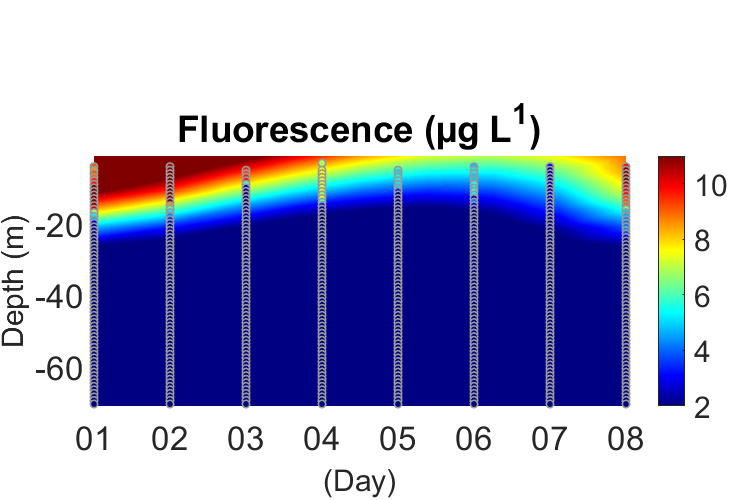

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,Fluo_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Fluorescence (µg L^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([2 11]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(FluoNSM)),-depthSM(isfinite(FluoNSM)),20,FluoNSM(isfinite(FluoNSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S3_Fluo.png','Resolution',300)

## Turb

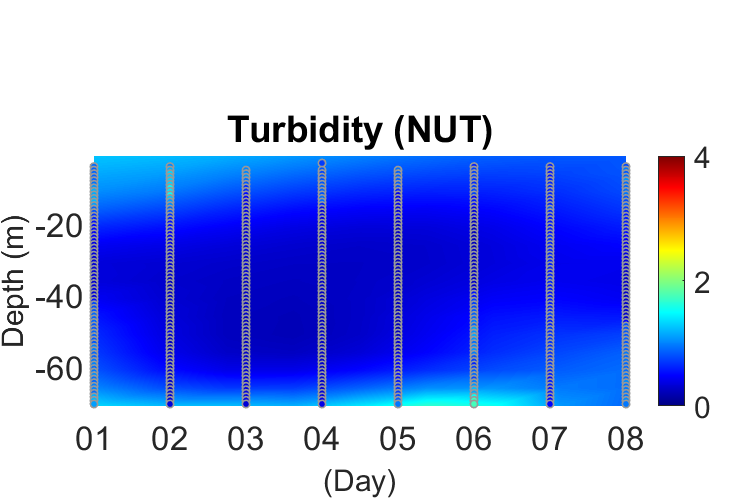

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,Turb_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'Turbidity (NUT)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 4]);  % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(TurbSM)),-depthSM(isfinite(TurbSM)),20,TurbSM(isfinite(TurbSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S3_Turb.png','Resolution',300)

## Par

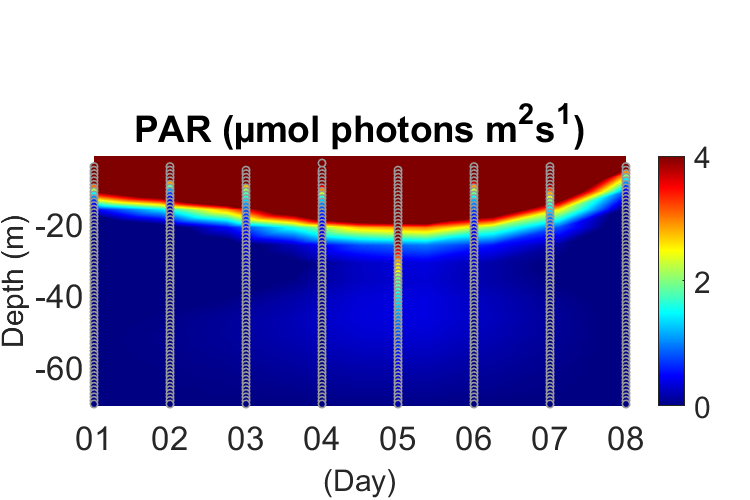

figure()

set(gcf,'PaperUnits','centimeters');
xSize=12; % Ancho
ySize=8; % Alto
xLeft=(12-xSize)/2;
yTop=(12-ySize)/2;
set(gcf,'PaperPosition',[xLeft yTop xSize ySize]);
set(gcf,'Position',[xLeft yTop xSize*50 ySize*50]);
set(gcf,'color',[1 1 1]);

xt=1.5/xSize;
yt=1.5/ySize;
wt=(10)/xSize; % Ancho
ht=(4)/ySize; % Alto
axes('position',[xt yt wt ht]);

pcolor(dateINTSM,-presINT,Par_INT_SM); %representas tu variable. primero colocas x(en mi caso date, que es el tiempo), luego y (en mi caso la presión en negativo) y luego tu variable de color (mi caso nitrato)
% shading flat; %esto es para que no te pinte una malla de cuadrados negros, así se ve más fluido el gráfico (hay otro que es interp en lugar de flat que lo suaviza mas aun)
shading interp
datetick('x','dd'); %esto tu no lo pones, porque no tienes tiempo en el eje x. para ver cómo se ponen las etiquetas, vete al otro que te pasé, al de cris
% xlim([dateN_I01(1)-0.008 dateN_I01(end)+0.08]); %esto no hace falta, es para eliminar huecos en blanco alrededor del gráfico. lo ajustas al valor máximo y mínimo de tus variables x e y
% ylim([-34.5 0]);

title ({'PAR (µmol photons m^2s^1)'});
ax=gca;
ax.FontSize = 20;
ylabel('Depth (m)', 'FontSize',18); %nombre de los ejes
xlab=xlabel('(Day)', 'FontSize',18);

colormap('jet'); cb=colorbar;
caxis([0 4]);   % masximos y minomos de la escala

hold on; %para superponer los puntos donde se cogió muestra de agua para medir nitrato:
scatter(dateSMN(isfinite(ParNSM)),-depthSM(isfinite(ParNSM)),20,ParNSM(isfinite(ParNSM)),'o','filled','MarkerEdgeColor',[.6 .6 .6],'LineWidth',1);

exportgraphics(gcf, 'Summer_S3_Par.png','Resolution',300)